# `Lista 4`

`Hubert Jackowski`

## `Układ RLC`

`RLC – skrótowe oznaczenie dla obwodów elektrycznych (w tym elektronicznych) składających się tylko z trzech podstawowych elementów pasywnych:rezystora, oznaczanego przez R (rezystancja),cewki, oznaczanej przez L (indukcyjność),kondensatorów, oznaczanych przez C (pojemność).`

#### `MODEL`

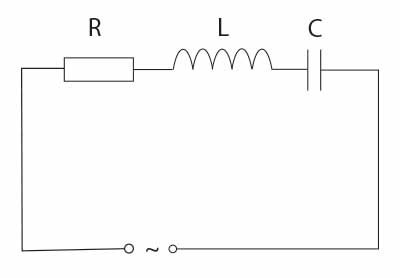

`Figure 1: Fizyczny model układu RLC`

`Figure 2: Realizacja modelu układu RLC za pomocą biblioteki sympy w języku Python`

`Figure 3: Realizacja modelu układu RLC za pomocą metody scipy.integrate.odeint w języku Python`

#### `OBSERWACJE`

`1. WYKRESY SYGNAŁÓW`

`Figure 7: Wykresy x(t) (niebieski), y(t) (pomarańczowy), z(x) (zielony) układu Lorentza metodą Eulera dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

`3. ŚREDNI BŁĄD APROKSYMACJI`

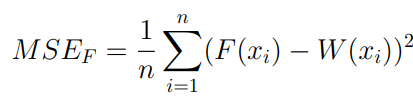

`Figure 17: Matematyczny wzór średniego błędu kwadratowego`

`Obliczymy średni błąd kwadratowy każdego sygnału za pomocą wzoru [Figure 17]:`

`Figure 18: Realizacja średniego błędu kwadratowego w języku Python`

- `dt = 0.001`

Model Lorenza:        δx = 0.19591265      δy = 0.40308504      δz = 0.63858806
Model Lotki-Volterry: δx = 2.28737774e-04  δy = 08.76694501e-05

- `dt = 0.01`

Model Lorenza:        δx = 176.65041139    δy = 195.93848631    δz =  66.78692278
Model Lotki-Volterry: δx = 0.02694779      δy = 0.01025241

- `dt = 0.02`

Model Lorenza:        δx = 155.92353612    δy = 187.39329765    δz =  72.94273338
Model Lotki-Volterry: δx = 0.13041354      δy = 0.0490712

`Figure 19: Średnie błędy kwadratowe dla dt = {0.001, 0.01, 0.02} w języku Python`

#### `WNIOSKI`

`Obie metody wyliczania układów są algorytmami rozwiązywania równań różniczkowych, zatem spodziewać możemy się, że w zależności od doboru dyskretnego kroku czasowego, otrzymany wynik będzie jedynie przybliżeniem rozwiązania. Metoda odeint wykorzystuje algorytm lsoda, który dynamicznie dostosowywuje sposób podejścia do rozwiązania ODE (wybierając pomiędzy różnymi metodami rozwiązywania ODE takimi jak metoda Runge-Kutta), z tego powodu obserwujemy, że szybciej zbiega on do rzeczywistego rozwiązania niż metoda Eulera. Jest on również z tego powodu stosunkowo mniej wrażliwy na niewiekie zmiany dt dla większości układów niż algorytm Eulera. Wciąż jednak, wybór kroku czasowego dt jest znaczący, ponieważ nie dokonujemy dyskretyzacji modelu, a rekurencyjnego podejścia rozwiązania numerycznego, co sprawia, że błędy wynikające z doboru dt nakładają się wraz z każdą iteracją, co uwidacznia się dla średnich kwadratowych błędów aproksymacji.`

`LITERATURA`

`[1] J.D. Murray: Wprowadzenie do Biomatematyki. Warszawa: Wydawnictwo Naukowe PWN, 2006.`

`[2] Edward N. Lorenz: Deterministic Nonperiodic Flow. „J.Atmos.Sci.”. 20 (2), s. 130–141, 1963.`

`[3] Robert Perliński: Aproksymacja II Metody numeryczne.`